# Train Network for Image Classification

*The purpose of this code is to train a CNN to classify images as "scissor," "stone," or "paper" using the provided dataset, which can correctly classify new images of scissors, stone, or paper with high accuracy.*

`(image reference: `[`https://www.kaggle.com/datasets/drgfreeman/rockpaperscissors?resource=download)`](https://www.kaggle.com/datasets/drgfreeman/rockpaperscissors?resource=download))

Loads the image dataset and creates an **ImageDatastore object**, which is used to manage a collection of image files. 

(The option 'IncludeSubfolders' is set to true to include all images within the subfolders and 'FileExtensions' is set to '.png' to include only PNG images. The last argument 'LabelSource' is set to 'foldernames', which means that the labels for the images will be taken from the names of the folders in which the images are stored.)

imds = imageDatastore('dataImages','IncludeSubfolders',true,'FileExtensions','.png','LabelSource','foldernames'); 

Display the label name and each count.

tbl = countEachLabel(imds)

Randomly selects 20 images from the dataset, and displays them.

figure
numImages = numel(imds.Labels);  %3408
idx = randperm(numImages,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{idx(i)});
    drawnow;
end

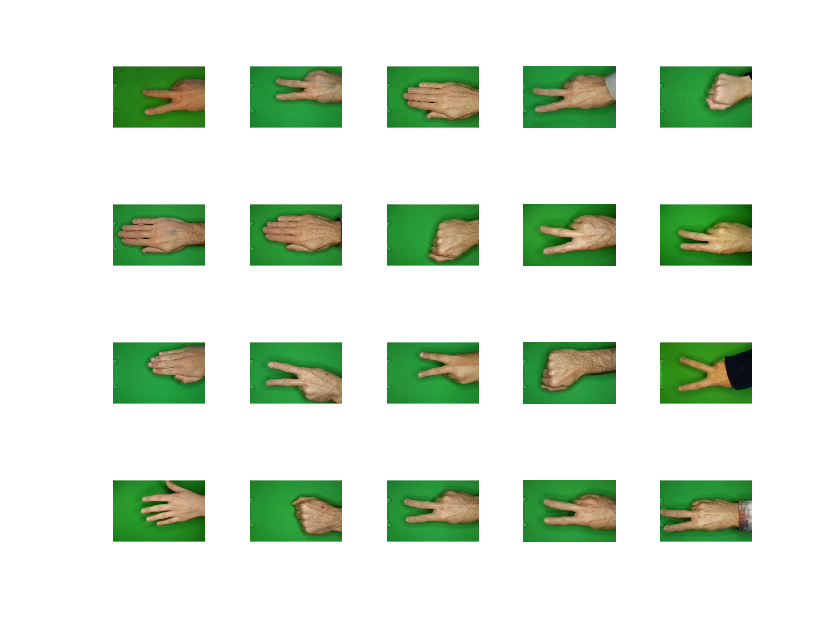

Splits the dataset into a **training set** and a **validation set**, with 70% of the data goes to the training set and 30% goes to the validation set.

(The first argument is the ImageDatastore object, the second argument is the percentage of the images that will be used for training and the remaining images will be used for validation.)

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

Counts the total number of images for imds, imdsTrain and imdsValidation

%圖片總數
numImages = length(imds.Files);  %2188
numTrainImages = length(imdsTrain.Files);  %1531
numValidationImages = length(imdsValidation.Files);  %657

Gets the size of one of the images and uses it to define the input layer of the network. The input layer is defined to have the same size as the images in the dataset (200x300x3).

- `img = readimage(imds, 1)`:  reading an image from the ImageDatastore, the first argument is the ImageDatastore object, the second argument is the index of the image to be read.

- `imgSize = size(img)`: getting the size of the image.

- `inputLayer = imageInputLayer([imgSize(1) imgSize(2) imgSize(3)])`: creating an input layer for the network, the argument passed to the function is the size of the image, in this case 200x300x3.

img = readimage(imds, 1);  %200*300*3(height*weight*channel size), if the image is grayscale image, the channel size is 1; if it's color image, the size is 3
imgSize = size(img); 

inputLayer = imageInputLayer([imgSize(1) imgSize(2) imgSize(3)]); 

**Defines the layers** of the network. The architecture of the network includes a convolutional layer, a batch normalization layer, a ReLU activation layer, a max pooling layer, and a fully connected layer with 3 outputs.

layers = [ 
    inputLayer 
    convolution2dLayer(3,8,'Padding','same') 
    batchNormalizationLayer 
    reluLayer 
    maxPooling2dLayer(2,'Stride',2) 
    fullyConnectedLayer(3)  %paper-scissiors-stone(3 classes)
    softmaxLayer 
    classificationLayer];

**Defines the training options** for the network. The options include using the "sgdm" optimization algorithm, an initial learning rate of 0.001, a maximum number of 20 epochs, shuffling the data every epoch, using the "imdsValidation" dataset for validation, validating every 30 epochs, not displaying verbose output, and plotting the training progress.

options = trainingOptions('sgdm', ... 
    'InitialLearnRate',0.001, ... 
    'MaxEpochs',20, ... 
    'Shuffle','every-epoch', ... 
    'ValidationData',imdsValidation, ... 
    'ValidationFrequency',30, ... 
    'Verbose',false, ... 
    'Plots','training-progress');

**Trains the network**, using the "imdsTrain" dataset and the defined layers and options.

net = trainNetwork(imdsTrain,layers,options);

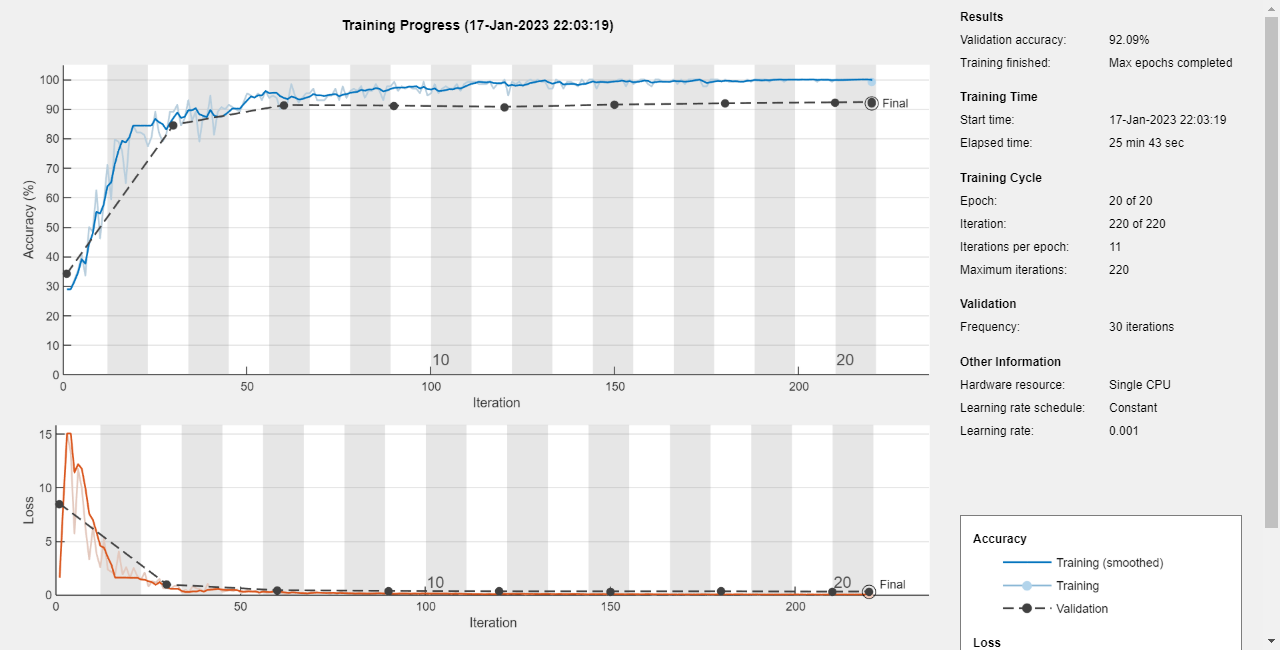

After the training, predict the labels for the images in the validation set. Then, **calculate the accuracy** of the predictions by comparing the predicted labels to the true labels of the validation set.

## *(accuracy = 0.9209)*

predictedLabels = classify(net, imdsValidation);
trueLabels = imdsValidation.Labels;

accuracy = mean(predictedLabels == trueLabels)

Converts the predicted labels and true labels from categorical format to double format(because both of them should be in the **same format** before comparing), and **calculate the root mean squared error (RMSE)** between the predicted labels and true labels.

## ***(rmse = 0.4017)***

predictedLabels = double(predictedLabels);
trueLabels = double(imdsValidation.Labels);

rmse = sqrt(mean((predictedLabels - trueLabels).^2))

**Visualize the network** and its properties.

analyzeNetwork(net)